# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table) and interpolation

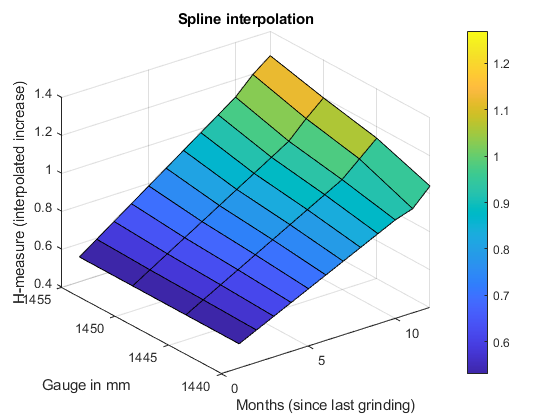

% read lookup tables
[H_table_MB5,H_table_MB6] = read_input_data();

% plot table
%plot_figure('H_table_heatmap', H_table_MB5);

% interpolations of H_table
H_table_interpol = interpolation(H_table_MB5);

% visualize the interpolated H_tables
% plot_figure('interpolation_heatmap', H_table_interpol)

## Graph construction

lcc_cost = get_lcc(maint_strategy);


% gauge for MB6
Xq_MB6 = [1450 1455];

% find the corresponding lifetime in years for scenario 2 
y_s2 = zeros(size(avg_yearly_gauge_widening));
for t=1:size(avg_yearly_gauge_widening,2)
    nb_tamping = 0;
    H_curr = 0;
    gauge_curr = 1440;
    for m=linspace(12,156,13) % over 13 years maximum
        % gauge increase after X months
        gauge_curr = gauge_curr+ avg_yearly_gauge_widening(t);
        % corresponding increase in H measure (after 1450mm)
        if(gauge_curr<1450)
            H_curr = H_curr + H_table_MB6(1,12);
        elseif(gauge_curr>=1450 && gauge_curr<=1455)
            H_curr = H_curr + interp2(Xq_MB6, Yq, H_table_MB6(:,Yq)', gauge_curr, 12,'linear');
        elseif(gauge_curr>1455)
            nb_tamping = nb_tamping + 1;
            gauge_curr = 1440;
            H_curr = H_curr + interp2(Xq_MB6, Yq, H_table_MB6(:,Yq)', 1455, 12,'linear');
        end
        % stop if we need to renew the rail
        if(H_curr>=H_max)
            break;
        else
            y_s2(t) = y_s2(t) + 1;
        end
    end
    if(avg_yearly_gauge_widening(t)==1.5)
        H_curr
        gauge_curr
        y_s2(1,t)
        nb_tamping
    end
    y_s2(t) = floor(y_s2(t));
end

% find the corresponding lifetime in years for scenario 1 (grinding each 6 months)
y_s3 = zeros(size(avg_yearly_gauge_widening));
for t=1:size(avg_yearly_gauge_widening,2)
    nb_tamping = 0;
    H_curr = 0;
    gauge_curr = 1440;
    for m=linspace(6,156,26) % over 13 years maximum
        % gauge increase after 6 months
        gauge_curr = gauge_curr + avg_yearly_gauge_widening(t)/2;
        % corresponding increase in H measure
        H_curr = H_curr + interp2(Xq, Yq, H_table_MB5(:,Yq)', gauge_curr, 6,'spline');
        % stop if we need to renew the rail
        if(gauge_curr>=1450)
            nb_tamping = nb_tamping + 1;
            gauge_curr = 1440;
        end
        if(H_curr>=H_max)
            break;
        else
            y_s3(t) = y_s3(t) + 1/2;
        end
    end
    if(avg_yearly_gauge_widening(t)==1.5)
        H_curr
        gauge_curr
        y_s3(1,t)
        nb_tamping
    end
    y_s3(t) = floor(y_s3(t));
end

## Plot results

hold off
figure
plot(avg_yearly_gauge_widening,y_s1','LineWidth',1.5, 'LineStyle',"-")
hold on
plot(avg_yearly_gauge_widening,y_s2',"+",'LineWidth',1.5, 'LineStyle',"--")
plot(avg_yearly_gauge_widening,y_s3',"x",'LineWidth',1.5)%, 'LineStyle',":")
legend('Scenario S1', 'S2', 'S3', 'FontSize', 16)
xlabel('Average yearly gauge widening (in mm)','FontSize', 16)
ylabel('Expected lifetime (in years)', 'FontSize', 16)